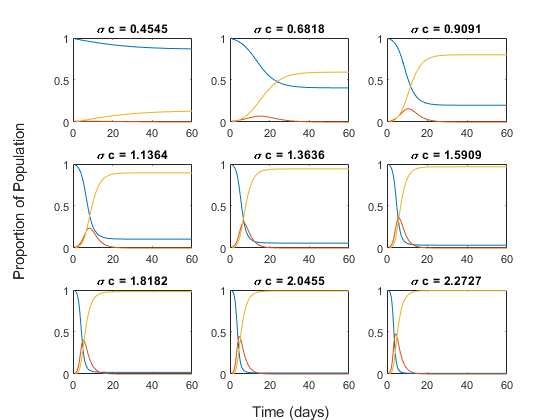

tspan = [1 60];

N0 = [0.99 0.01 0];
%Model 1
%fix rho
R0 = 1:0.5:5 ;%if below 1 then no epidemic
rho = 1/2.2;
for i = 1:1:9
    b = rho*R0(i);
    [t,S] = ode23s(@(t, N) Model1(t,N,b,rho), tspan, N0) ;
    subplot (3,3,i)    
    plot(t, S(:,1), t,S(:,2),t,S(:,3))
    title(['\sigma c = ', num2str(round(b,4))])
end
[ax1,h1]=suplabel('Time (days)', 'x', [.1 .1 .84 .84]);
[ax2,h2]=suplabel('Proportion of Population','y', [.1 .1 .84 .84]);

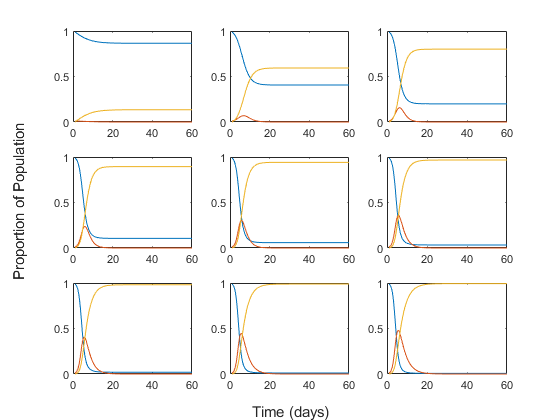


%fix sigma*c
figure
R0 = 1:0.5:5;
b = 1.66;
for i = 1:1:9
    rho = b/R0(i);
    [t,S] = ode23s(@(t, N) Model1(t,N,b,rho), tspan, N0) ;
    subplot(3,3, i)
    plot(t, S(:,1), t,S(:,2),t,S(:,3))
end
[ax1,h1]=suplabel('Time (days)', 'x', [.1 .1 .84 .84]);
[ax2,h2]=suplabel('Proportion of Population','y', [.1 .1 .84 .84]);

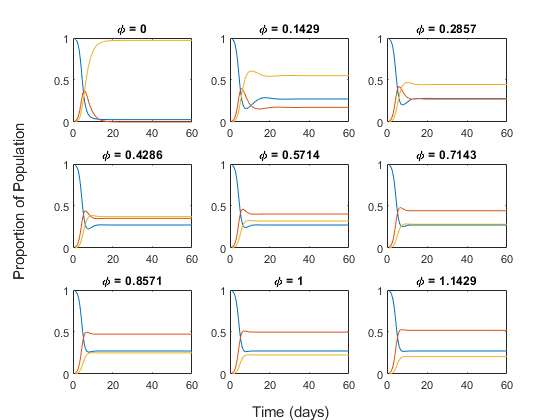


%Model 2
%fix rho and sigma*c
figure
phi = 0:1/7:9/7;
b = 1.66;
rho = 1/2.2;
for i = 1:1:9
    [t, S] = ode23s(@(t, N) Model2(t,N,b,rho,phi(i)), tspan, N0) ;
    subplot(3,3, i)
    plot(t, S(:,1), t,S(:,2),t,S(:,3))
    title(['\phi = ', num2str(round(phi(i),4))])
end
[ax1,h1]=suplabel('Time (days)', 'x', [.1 .1 .84 .84]);
[ax2,h2]=suplabel('Proportion of Population','y', [.1 .1 .84 .84]);

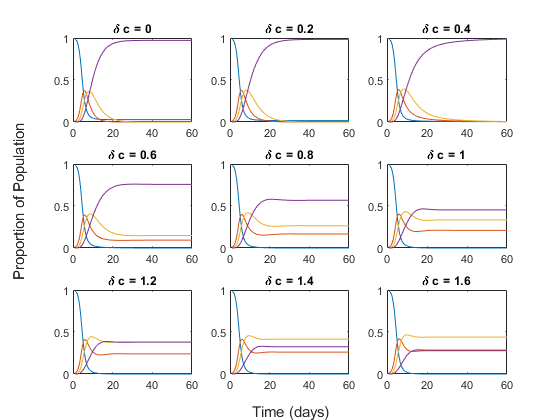


%Model 3
%fix phi (waning immunity)
N0 = [0.99 0.01 0 0];
phi = 2/7;
b = 1.66;
rho = 1/2.2;
%since b2<b
b2 = 0:0.20:b;
figure
for i = 1:1:9
    [t, S] = ode23s(@(t, N) Model3(t,N,b,rho,phi,b2(i)), tspan, N0) ;
    subplot(3,3, i)
    plot(t, S(:,1), t,S(:,2),t,S(:,3),t,S(:,4))
    title(['\delta c = ', num2str(b2(i))])
end
[ax1,h1]=suplabel('Time (days)', 'x', [.1 .1 .84 .84]);
[ax2,h2]=suplabel('Proportion of Population','y', [.1 .1 .84 .84]);

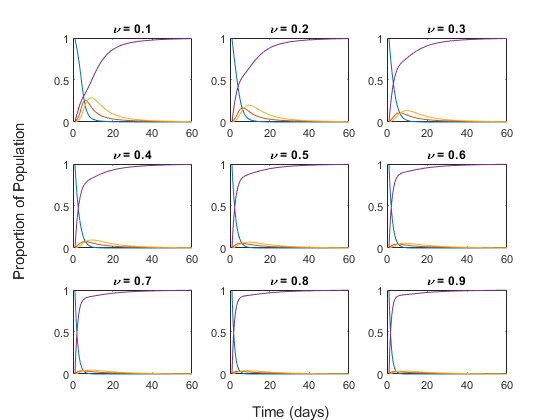

%Model 4 leaky vaccine

N0 = [0.99 0.01 0 0];
phi = 2/7;
b = 1.66;
rho = 1/2.2;
%since b2<b
b2 = 0.4;
nu = .1:.1:0.9;
figure
for i = 1:1:9
    [t, S] = ode23s(@(t, N) Model4(t,N,b,rho,phi,b2, nu(i)), tspan, N0) ;
    subplot(3,3, i)
    plot(t, S(:,1), t,S(:,2),t,S(:,3),t,S(:,4))
    title(['\nu = ', num2str(round(nu(i),4))])
end
[ax1,h1]=suplabel('Time (days)', 'x', [.1 .1 .84 .84]);
[ax2,h2]=suplabel('Proportion of Population','y', [.1 .1 .84 .84]);